# Pdf and Cdf of Continuous Uniform RV

Note: this script reproduces the figure of the continuous uniform RV in Section 2.2.1 of **Statistics for Chemical Engineers**, with a = -1 and b = 1. Victor Z UW-Madison, 2020 pdf and cdf of a continuous uniform RV

clc; clear all; close all hidden;

a=-1; b=+1;
x=linspace(-2,2);

figure(1)

## Realizations

generate realizations

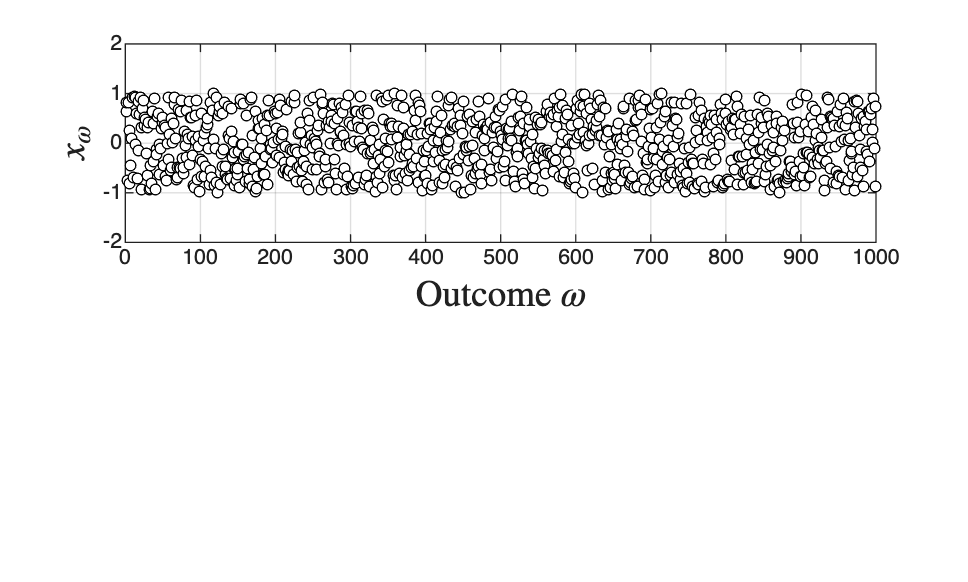

S=1000;
rng(0);
X = unifrnd(a,b,S,1);
figure(1)
subplot(2,2,[1 2])
plot(X,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$','Interpreter','latex','FontSize',14)
grid on
yticks([-2 -1 0 1 2])
axis([0 S -2 2])

## Pdf

visualize pdf

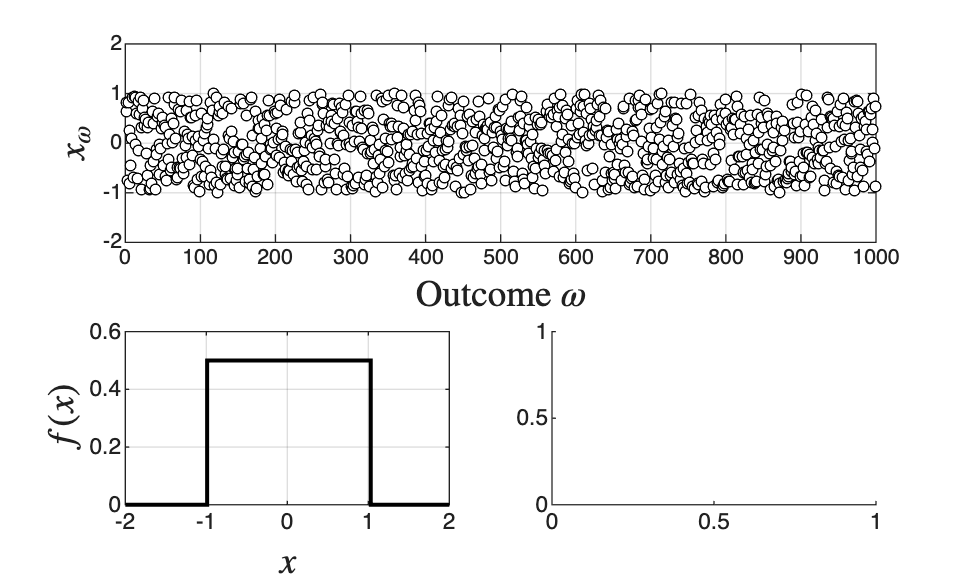

subplot(2,2,3)
stairs(x,unifpdf(x,a,b),'-','Color','black','LineWidth',1.5)
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)

subplot(2,2,4)

## Cdf

visualize cdf

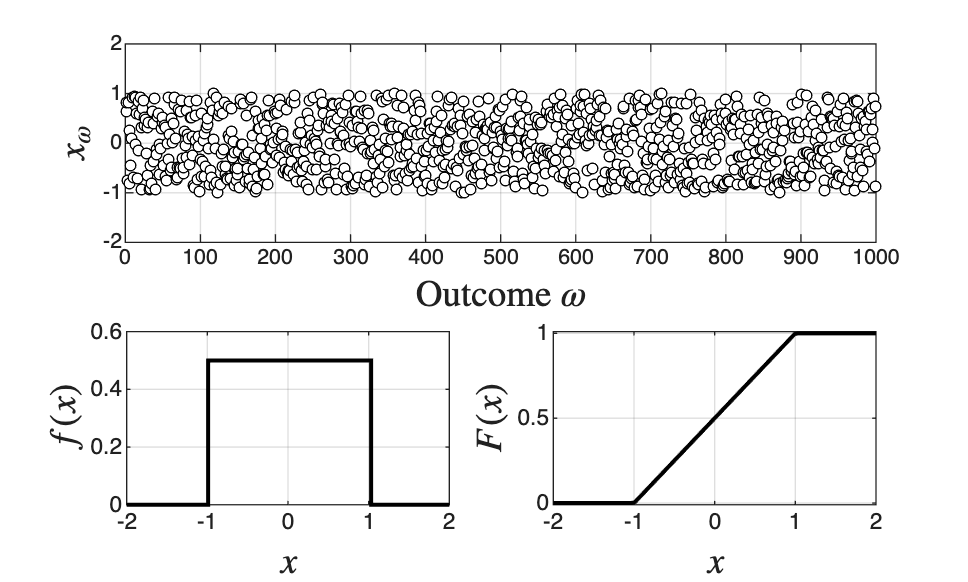

plot(x,unifcdf(x,a,b),'-','Color','black','LineWidth',1.5)
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
title('')
axis([-2 2 -0.01 1.01])

print -depsc ch2_pdfcdfuniformc.eps

## Note

The pdf is flat on [a, b] and the cdf grows linearly from 0 to 1.